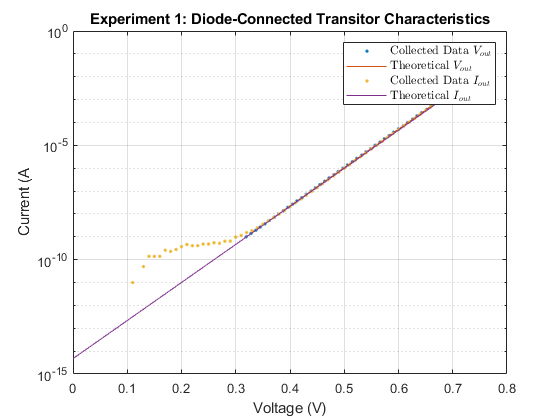

%Experiment 1: Diode-Connected Transitor Characteristics
clear
clf
load('Experiment 1/IinVout/Vout.mat')
load('Experiment 1/IinVout/Iin.mat')
semilogy(Vout, Iin, '.')
hold on
title("Experiment 1: Diode-Connected Transitor Characteristics")
xlabel("Voltage (V)")
ylabel("Current (A")
grid on
%plot(Iin,Vout,".")

%line of best fit
[first, last, mmax, bmax, Nmax]=linefit(Vout, log(Iin), 5e-4);
Is = exp(bmax);
Ut = 1/mmax;

th_Vout = Ut*log((Iin)/Is);
%plot(Iin, th_Vout)
semilogy(th_Vout, Iin)


%Vin Iout
load('Experiment 1/VinIout/Vin.mat')
load('Experiment 1/VinIout/Iout.mat')
%plot(Vin, Iout,".")
semilogy(Vin, Iout, '.')

%line of best fit
[first2, last2, mmax2, bmax2, Nmax2]=linefit(Vin, log(Iout), 5e-4);
Is2 = exp(bmax2);
Ut2 = 1/mmax2;

th_Iout = Is2*exp(Vin/Ut2);
th_Vout = Ut2*log((Iin)/Is2);
%plot(Iin, th_Vout)
semilogy(Vin, th_Iout)

legend("Collected Data $V_{out}$", "Theoretical $V_{out}$", "Collected Data $I_{out}$", "Theoretical $I_{out}$", "Interpreter", "latex")

hold off

%Experiment 1: 
clf
R = diff(Vout)./diff(Iin)

R = 	1.0e+07 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0009    0.0011    0.0017    0.0021    0.0032    0.0040    0.0062    0.0077    0.0113    0.0157    0.0205    0.0321    0.0397    0.0620    0.0766    0.1197    0.1478    0.2311    0.2854    0.4461    0.5510    0.8613    1.0638    1.6630    2.2593


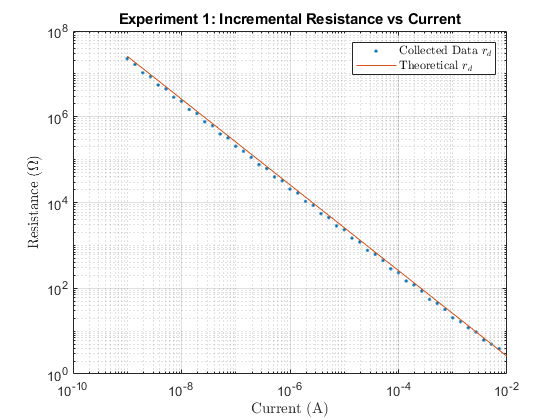

loglog(Iin(2:end), R, '.')
hold on
title("Experiment 1: Incremental Resistance vs Current")
xlabel("Current (A)", "Interpreter", "latex")
ylabel("Resistance ($\Omega$)", "Interpreter", "latex")
grid on

% line of best fit
th_R = Ut./Iin; % = dv/dI
loglog(Iin, th_R)

legend("Collected Data $r_{d}$", "Theoretical $r_{d}$", "Interpreter", "latex")